clear; clc; close all;

%% =========================
% Robot dimensions
%% =========================
b  = 2.5;
L1 = 5;
L2 = 22;
L3 = 18;
L4 = 10;

%% =========================
% Chessboard parameters
%% =========================
board_size   = 40;
board_x_min  = 0;
board_y_min  = -board_size/2;
board_z      = 0;
num_squares  = 8;

%% =========================
% USER INPUT: target point
%% =========================
target = [39, -19, 9.5];   % [x, y, z] in cm

% Preferred mode 1: gripper vertical
gamma_des_vertical = pi;

% Fallback mode 2: gripper inline with forearm
q4_straight = 0;

% Wrist rotation
q5_des = 0;   % single angle in rad

% Preferred solution index when both are valid
solution_to_plot = 1;

%% =========================
% Joint limits (degrees)
%% =========================
q1_lim_deg = [-180, 180];
q2_lim_deg_1 = [-90, -10];
q2_lim_deg_2 = [ 10,  90];

q3_lim_deg_1 = [-120, -10];
q3_lim_deg_2 = [  10, 120];

q4_lim_deg_1 = [-120, 0];
q4_lim_deg_2 = [  0, 120];

q5_lim_deg = [-180, 180];

%% =========================
% Default zero position
%% =========================
q_zero = [0 0 0 0 0];
q = q_zero;
q_deg = rad2deg(q_zero);

%% =========================
% Target values
%% =========================
xd = target(1);
yd = target(2);
zd = target(3);

% Base angle
q1 = atan2(yd, xd) + pi;

% Horizontal radial distance
r = sqrt(xd^2 + yd^2);

%% =========================
% Global result flags
%% =========================
selected_status = 'ZERO POSITION';
selected_status_msg = 'No valid solution found.';
selected_solution_idx = 0;
selected_mode = 'NONE';

q_sol1 = nan(1,5);
q_sol2 = nan(1,5);
q_sol1_deg = nan(1,5);
q_sol2_deg = nan(1,5);
is_valid_1 = false;
is_valid_2 = false;
msg_1 = 'Not computed';
msg_2 = 'Not computed';

%% =========================================================
% TRY 1: gripper vertical  -> gamma = pi
%% =========================================================
disp('======================================================');

disp('TRY 1: Gripper vertical');

TRY 1: Gripper vertical


disp('Condition: gamma = pi');

Condition: gamma = pi


disp('======================================================');


rw = r  - b - L4*sin(gamma_des_vertical);
zw = zd - L1 - L4*cos(gamma_des_vertical);

[q_sol1_A, q_sol2_A, q_sol1_deg_A, q_sol2_deg_A, ...
 is_valid_1_A, is_valid_2_A, msg_1_A, msg_2_A, reachable_A] = ...
    solve_with_gamma(q1, rw, zw, gamma_des_vertical, q5_des, ...
    q1_lim_deg, q2_lim_deg_1, q2_lim_deg_2, ...
    q3_lim_deg_1, q3_lim_deg_2, ...
    q4_lim_deg_1, q4_lim_deg_2, q5_lim_deg, ...
    L2, L3);

print_two_solutions('Mode 1: gamma = pi', ...
    q_sol1_A, q_sol2_A, q_sol1_deg_A, q_sol2_deg_A, ...
    is_valid_1_A, is_valid_2_A, msg_1_A, msg_2_A);

----- Mode 1: gamma = pi -----
Solution 1 (radians):
   NaN   NaN   NaN   NaN   NaN

Solution 1 (degrees):
   NaN   NaN   NaN   NaN   NaN

Solution 1 validity: INVALID -> Outside reachable workspace
 
Solution 2 (radians):
   NaN   NaN   NaN   NaN   NaN

Solution 2 (degrees):
   NaN   NaN   NaN   NaN   NaN

Solution 2 validity: INVALID -> Outside reachable workspace
 



valid_vertical = reachable_A && (is_valid_1_A || is_valid_2_A);

if valid_vertical
    selected_mode = 'vertical';

    q_sol1 = q_sol1_A;
    q_sol2 = q_sol2_A;
    q_sol1_deg = q_sol1_deg_A;
    q_sol2_deg = q_sol2_deg_A;
    is_valid_1 = is_valid_1_A;
    is_valid_2 = is_valid_2_A;
    msg_1 = msg_1_A;
    msg_2 = msg_2_A;

    if solution_to_plot == 1 && is_valid_1
        q = q_sol1;
        q_deg = q_sol1_deg;
        selected_solution_idx = 1;
        selected_status = 'VALID';
        selected_status_msg = msg_1;
    elseif solution_to_plot == 2 && is_valid_2
        q = q_sol2;
        q_deg = q_sol2_deg;
        selected_solution_idx = 2;
        selected_status = 'VALID';
        selected_status_msg = msg_2;
    else
        if is_valid_1
            q = q_sol1;
            q_deg = q_sol1_deg;
            selected_solution_idx = 1;
            selected_status = 'VALID';
            selected_status_msg = msg_1;
        else
            q = q_sol2;
            q_deg = q_sol2_deg;
            selected_solution_idx = 2;
            selected_status = 'VALID';
            selected_status_msg = msg_2;
        end
    end

else
    %% =========================================================
    % TRY 2: gripper inline with forearm -> q4 = 0
    %% =========================================================
    disp(' ');
    disp('======================================================');
    disp('TRY 2: Gripper inline with forearm');
    disp('Condition: q4 = 0');
    disp('======================================================');

    [q_sol1_B, q_sol2_B, q_sol1_deg_B, q_sol2_deg_B, ...
     is_valid_1_B, is_valid_2_B, msg_1_B, msg_2_B, reachable_B] = ...
        solve_with_fixed_q4(q1, r, zd, q4_straight, q5_des, ...
        b, L1, L2, L3, L4, ...
        q1_lim_deg, q2_lim_deg_1, q2_lim_deg_2, ...
        q3_lim_deg_1, q3_lim_deg_2, ...
        q4_lim_deg_1, q4_lim_deg_2, q5_lim_deg);

    print_two_solutions('Mode 2: q4 = 0', ...
        q_sol1_B, q_sol2_B, q_sol1_deg_B, q_sol2_deg_B, ...
        is_valid_1_B, is_valid_2_B, msg_1_B, msg_2_B);

    valid_straight = reachable_B && (is_valid_1_B || is_valid_2_B);

    if valid_straight
        selected_mode = 'straight';

        q_sol1 = q_sol1_B;
        q_sol2 = q_sol2_B;
        q_sol1_deg = q_sol1_deg_B;
        q_sol2_deg = q_sol2_deg_B;
        is_valid_1 = is_valid_1_B;
        is_valid_2 = is_valid_2_B;
        msg_1 = msg_1_B;
        msg_2 = msg_2_B;

        if solution_to_plot == 1 && is_valid_1
            q = q_sol1;
            q_deg = q_sol1_deg;
            selected_solution_idx = 1;
            selected_status = 'VALID';
            selected_status_msg = msg_1;
        elseif solution_to_plot == 2 && is_valid_2
            q = q_sol2;
            q_deg = q_sol2_deg;
            selected_solution_idx = 2;
            selected_status = 'VALID';
            selected_status_msg = msg_2;
        else
            if is_valid_1
                q = q_sol1;
                q_deg = q_sol1_deg;
                selected_solution_idx = 1;
                selected_status = 'VALID';
                selected_status_msg = msg_1;
            else
                q = q_sol2;
                q_deg = q_sol2_deg;
                selected_solution_idx = 2;
                selected_status = 'VALID';
                selected_status_msg = msg_2;
            end
        end
    else
        selected_mode = 'NONE';
        selected_status = 'ZERO POSITION';
        selected_status_msg = 'No valid solution in either vertical mode or straight-line mode.';
        q = q_zero;
        q_deg = rad2deg(q_zero);
    end
end

TRY 2: Gripper inline with forearm


Condition: q4 = 0


----- Mode 2: q4 = 0 -----
Solution 1 (radians):
    2.6883   -0.5839    1.2198         0         0

Solution 1 (degrees):
  154.0256  -33.4568   69.8900         0         0

Solution 1 validity: VALID
 
Solution 2 (radians):
    2.6883    0.8032   -1.2198         0         0

Solution 2 (degrees):
  154.0256   46.0197  -69.8900         0         0

Solution 2 validity: VALID
 


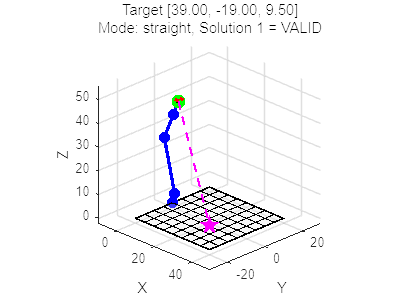


if strcmp(selected_status, 'ZERO POSITION')
    disp(' ');
    disp('================ IK Result ================');
    disp(selected_status_msg);
    disp('Plotting robot at zero position.');
end

%% =========================
% Forward kinematics for plotted configuration
%% =========================
DH_table = [ ...
   -b,   pi/2,   L1,      q(1);
    L2,    0,     0,      q(2) + pi/2;
    L3,    0,     0,      q(3);
     0,   -pi/2,  0,      q(4) - pi/2;
     0,    0,    L4,      q(5)
];

n = size(DH_table,1);

T = eye(4);
origins = zeros(3,n+1);
origins(:,1) = [0;0;0];
T_all = cell(1,n);

for i = 1:n
    a     = DH_table(i,1);
    alpha = DH_table(i,2);
    d     = DH_table(i,3);
    theta = DH_table(i,4);

    A_i = DH_std(a, alpha, d, theta);
    T = T * A_i;

    T_all{i} = T;
    origins(:,i+1) = T(1:3,4);
end

ee_pos = origins(:,end);

%% =========================
% Plot
%% =========================
figure; hold on; grid on; axis equal;

% Chessboard
x1 = board_x_min;
x2 = board_x_min + board_size;
y1 = board_y_min;
y2 = board_y_min + board_size;
z0 = board_z;

fill3([x1 x2 x2 x1], ...
      [y1 y1 y2 y2], ...
      [z0 z0 z0 z0], ...
      [0.9 0.9 0.9], ...
      'FaceAlpha', 0.25, ...
      'EdgeColor', 'k', ...
      'LineWidth', 1.2);

square_size = board_size / num_squares;
for k = 0:num_squares
    xg = x1 + k*square_size;
    plot3([xg xg], [y1 y2], [z0 z0], 'k', 'LineWidth', 0.8);

    yg = y1 + k*square_size;
    plot3([x1 x2], [yg yg], [z0 z0], 'k', 'LineWidth', 0.8);
end

% Robot
plot3(origins(1,:), origins(2,:), origins(3,:), '-o', ...
      'Color', 'b', ...
      'LineWidth', 2.5, ...
      'MarkerSize', 6, ...
      'MarkerFaceColor', 'b');

% Target point
plot3(target(1), target(2), target(3), 'mp', ...
      'MarkerSize', 14, ...
      'MarkerFaceColor', 'm');

% End-effector point
plot3(ee_pos(1), ee_pos(2), ee_pos(3), 'go', ...
      'MarkerSize', 10, ...
      'MarkerFaceColor', 'g');

% Dashed line
plot3([ee_pos(1), target(1)], ...
      [ee_pos(2), target(2)], ...
      [ee_pos(3), target(3)], ...
      'm--', 'LineWidth', 1.5);

%% =========================
% Draw gripper
%% =========================
T5 = T_all{5};

finger_length = 2.5;
finger_offset = 1;

p1_base_5 = [0;  finger_offset; 0; 1];
p1_tip_5  = [0;  finger_offset; finger_length; 1];

p2_base_5 = [0; -finger_offset; 0; 1];
p2_tip_5  = [0; -finger_offset; finger_length; 1];

p1_base_0 = T5 * p1_base_5;
p1_tip_0  = T5 * p1_tip_5;
p2_base_0 = T5 * p2_base_5;
p2_tip_0  = T5 * p2_tip_5;

plot3([p1_base_0(1), p1_tip_0(1)], ...
      [p1_base_0(2), p1_tip_0(2)], ...
      [p1_base_0(3), p1_tip_0(3)], 'r', 'LineWidth', 3);

plot3([p2_base_0(1), p2_tip_0(1)], ...
      [p2_base_0(2), p2_tip_0(2)], ...
      [p2_base_0(3), p2_tip_0(3)], 'r', 'LineWidth', 3);

plot3([p1_base_0(1), p2_base_0(1)], ...
      [p1_base_0(2), p2_base_0(2)], ...
      [p1_base_0(3), p2_base_0(3)], 'k', 'LineWidth', 2);

%% =========================
% Labels and title
%% =========================
xlabel('X');
ylabel('Y');
zlabel('Z');

if strcmp(selected_status, 'VALID')
    title(sprintf(['Target [%.2f, %.2f, %.2f]\n', ...
                   'Mode: %s, Solution %d = VALID'], ...
                   target(1), target(2), target(3), ...
                   selected_mode, selected_solution_idx));
else
    title(sprintf(['Target [%.2f, %.2f, %.2f]\n', ...
                   'No valid solution - robot shown at zero position'], ...
                   target(1), target(2), target(3)));
end

view(45,25);
xlim([min(-10, x1-5), x2+10]);
ylim([y1-10, y2+10]);
zlim([min(-2, z0-2), max([origins(3,:), target(3)])+10]);


%% =========================
% Numerical check
%% =========================
disp('================ Numerical Check ================');

================ Numerical Check ================


disp('Target point:');

Target point:


disp(target);

   39.0000  -19.0000    9.5000




disp('End-effector point from plotted configuration:');

End-effector point from plotted configuration:


disp(ee_pos.');

    6.2929   -3.0658   45.8820




disp('Position error norm:');

Position error norm:


disp(norm(ee_pos.' - target));

   51.4520




if strcmp(selected_status, 'VALID')
    disp('Selected solution (degrees):');
    disp(q_deg);
    disp('Selected solution status: VALID');
    disp(['Selected mode: ', selected_mode]);
else
    disp(selected_status_msg);
    disp('Robot plotted at zero position instead.');
end

Selected solution (degrees):


  154.0256  -33.4568   69.8900         0         0



Selected solution status: VALID


Selected mode: straight



%% =========================
% Standard DH function
%% =========================

function T = DH_std(a, alpha, d, theta)
T = [cos(theta), -sin(theta)*cos(alpha),  sin(theta)*sin(alpha), a*cos(theta);
     sin(theta),  cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta);
     0,           sin(alpha),             cos(alpha),            d;
     0,           0,                      0,                     1];
end

%% =========================
% Solve using fixed gamma
%% =========================
function [q_sol1, q_sol2, q_sol1_deg, q_sol2_deg, ...
          is_valid_1, is_valid_2, msg_1, msg_2, reachable] = ...
          solve_with_gamma(q1, rw, zw, gamma_des, q5_des, ...
          q1_lim_deg, q2_lim_deg_1, q2_lim_deg_2, ...
          q3_lim_deg_1, q3_lim_deg_2, ...
          q4_lim_deg_1, q4_lim_deg_2, q5_lim_deg, ...
          L2, L3)

q_sol1 = nan(1,5); q_sol2 = nan(1,5);
q_sol1_deg = nan(1,5); q_sol2_deg = nan(1,5);
is_valid_1 = false; is_valid_2 = false;
msg_1 = 'Not computed'; msg_2 = 'Not computed';
reachable = true;

cos_q3 = (rw^2 + zw^2 - L2^2 - L3^2) / (2*L2*L3);

if abs(cos_q3) > 1
    reachable = false;
    msg_1 = 'Outside reachable workspace';
    msg_2 = 'Outside reachable workspace';
    return;
end

q3_sol1 =  acos(cos_q3);
q3_sol2 = -acos(cos_q3);

q2_sol1 = atan2(rw, zw) - atan2(L3*sin(q3_sol1), L2 + L3*cos(q3_sol1));
q2_sol2 = atan2(rw, zw) - atan2(L3*sin(q3_sol2), L2 + L3*cos(q3_sol2));

q4_sol1 = gamma_des - q2_sol1 - q3_sol1;
q4_sol2 = gamma_des - q2_sol2 - q3_sol2;

q_sol1 = [q1, q2_sol1, q3_sol1, q4_sol1, q5_des];
q_sol2 = [q1, q2_sol2, q3_sol2, q4_sol2, q5_des];

q_sol1_deg = rad2deg(q_sol1);
q_sol2_deg = rad2deg(q_sol2);

[is_valid_1, msg_1] = check_joint_limits(q_sol1_deg, ...
    q1_lim_deg, q2_lim_deg_1, q2_lim_deg_2, ...
    q3_lim_deg_1, q3_lim_deg_2, ...
    q4_lim_deg_1, q4_lim_deg_2, q5_lim_deg);

[is_valid_2, msg_2] = check_joint_limits(q_sol2_deg, ...
    q1_lim_deg, q2_lim_deg_1, q2_lim_deg_2, ...
    q3_lim_deg_1, q3_lim_deg_2, ...
    q4_lim_deg_1, q4_lim_deg_2, q5_lim_deg);
end

%% =========================
% Solve using strict q4 = 0
%% =========================
function [q_sol1, q_sol2, q_sol1_deg, q_sol2_deg, ...
          is_valid_1, is_valid_2, msg_1, msg_2, reachable] = ...
          solve_with_fixed_q4(q1, r, zd, q4_fixed, q5_des, ...
          b, L1, L2, L3, L4, ...
          q1_lim_deg, q2_lim_deg_1, q2_lim_deg_2, ...
          q3_lim_deg_1, q3_lim_deg_2, ...
          q4_lim_deg_1, q4_lim_deg_2, q5_lim_deg)

q_sol1 = nan(1,5); q_sol2 = nan(1,5);
q_sol1_deg = nan(1,5); q_sol2_deg = nan(1,5);
is_valid_1 = false; is_valid_2 = false;
msg_1 = 'Not computed'; msg_2 = 'Not computed';
reachable = false;

% Strict q4 = 0:
% xeq in planar form:
% L2*cos(phi2) + L3*cos(phi2+q3) + L4*cos(phi2+q3) = rw_total
% L2*sin(phi2) + L3*sin(phi2+q3) + L4*sin(phi2+q3) = zw_total
%
% Under your current code style, equivalent compact way is:
% combine L3 and L4 because q4 = 0 means they stay collinear
L34 = L3 + L4;

rw = r - b;
zw = zd - L1;

cos_q3 = (rw^2 + zw^2 - L2^2 - L34^2) / (2*L2*L34);

if abs(cos_q3) > 1
    msg_1 = 'No strict q4 = 0 solution';
    msg_2 = 'No strict q4 = 0 solution';
    return;
end

reachable = true;

q3_sol1 =  acos(cos_q3);
q3_sol2 = -acos(cos_q3);

q2_sol1 = atan2(zw, rw) - atan2(L34*sin(q3_sol1), L2 + L34*cos(q3_sol1));
q2_sol2 = atan2(zw, rw) - atan2(L34*sin(q3_sol2), L2 + L34*cos(q3_sol2));

q4_sol1 = q4_fixed;
q4_sol2 = q4_fixed;

q_sol1 = [q1, q2_sol1, q3_sol1, q4_sol1, q5_des];
q_sol2 = [q1, q2_sol2, q3_sol2, q4_sol2, q5_des];

q_sol1_deg = rad2deg(q_sol1);
q_sol2_deg = rad2deg(q_sol2);

[is_valid_1, msg_1] = check_joint_limits(q_sol1_deg, ...
    q1_lim_deg, q2_lim_deg_1, q2_lim_deg_2, ...
    q3_lim_deg_1, q3_lim_deg_2, ...
    q4_lim_deg_1, q4_lim_deg_2, q5_lim_deg);

[is_valid_2, msg_2] = check_joint_limits(q_sol2_deg, ...
    q1_lim_deg, q2_lim_deg_1, q2_lim_deg_2, ...
    q3_lim_deg_1, q3_lim_deg_2, ...
    q4_lim_deg_1, q4_lim_deg_2, q5_lim_deg);
end

%% =========================
% Print two solutions
%% =========================
function print_two_solutions(title_str, ...
    q_sol1, q_sol2, q_sol1_deg, q_sol2_deg, ...
    is_valid_1, is_valid_2, msg_1, msg_2)

disp(['----- ', title_str, ' -----']);

disp('Solution 1 (radians):');
disp(q_sol1);
disp('Solution 1 (degrees):');
disp(q_sol1_deg);
if is_valid_1
    disp('Solution 1 validity: VALID');
else
    disp(['Solution 1 validity: INVALID -> ', msg_1]);
end
disp(' ');

disp('Solution 2 (radians):');
disp(q_sol2);
disp('Solution 2 (degrees):');
disp(q_sol2_deg);
if is_valid_2
    disp('Solution 2 validity: VALID');
else
    disp(['Solution 2 validity: INVALID -> ', msg_2]);
end
disp(' ');
end

%% =========================
% Joint limit checking function
%% =========================
function [is_valid, msg] = check_joint_limits(q_deg, ...
    q1_lim_deg, q2_lim_deg_1, q2_lim_deg_2, ...
    q3_lim_deg_1, q3_lim_deg_2, ...
    q4_lim_deg_1, q4_lim_deg_2, q5_lim_deg)

q1 = wrapTo180_local(q_deg(1));
q2 = wrapTo180_local(q_deg(2));
q3 = wrapTo180_local(q_deg(3));
q4 = wrapTo180_local(q_deg(4));
q5 = wrapTo180_local(q_deg(5));

is_valid = true;
msg = 'All joints within limits.';

if ~(q1 >= q1_lim_deg(1) && q1 <= q1_lim_deg(2))
    is_valid = false;
    msg = sprintf('q1 = %.2f deg outside [%g, %g]', q1, q1_lim_deg(1), q1_lim_deg(2));
    return;
end

q2_ok = (q2 >= q2_lim_deg_1(1) && q2 <= q2_lim_deg_1(2)) || ...
        (q2 >= q2_lim_deg_2(1) && q2 <= q2_lim_deg_2(2));
if ~q2_ok
    is_valid = false;
    msg = sprintf('q2 = %.2f deg outside allowed ranges', q2);
    return;
end

q3_ok = (q3 >= q3_lim_deg_1(1) && q3 <= q3_lim_deg_1(2)) || ...
        (q3 >= q3_lim_deg_2(1) && q3 <= q3_lim_deg_2(2));
if ~q3_ok
    is_valid = false;
    msg = sprintf('q3 = %.2f deg outside allowed ranges', q3);
    return;
end

q4_ok = (q4 >= q4_lim_deg_1(1) && q4 <= q4_lim_deg_1(2)) || ...
        (q4 >= q4_lim_deg_2(1) && q4 <= q4_lim_deg_2(2));
if ~q4_ok
    is_valid = false;
    msg = sprintf('q4 = %.2f deg outside allowed ranges', q4);
    return;
end

if ~(q5 >= q5_lim_deg(1) && q5 <= q5_lim_deg(2))
    is_valid = false;
    msg = sprintf('q5 = %.2f deg outside [%g, %g]', q5, q5_lim_deg(1), q5_lim_deg(2));
    return;
end
end

%% =========================
% Local wrap to [-180, 180]
%% =========================
function ang = wrapTo180_local(ang)
ang = mod(ang + 180, 360) - 180;
end